clc;
clear;
syms s ui uo R C I1 I2 I3 u1 u2 u3
eqs=[
    ui-u1==(I1+I2+I3)*R;
    u1==I1/(C*s);

    u1-u2==(I2+I3)*R;
    u2==I2/(C*s);

    u2-u3==I3*R;
    u3==I3/(C*s);

    uo==u3;
]

$$eqs = \left(\begin{array}{c} \mathrm{ui}-u_{1}=R\,\left(I_{1}+I_{2}+I_{3}\right)\\ u_{1}=\frac{I_{1}}{C\,s}\\ u_{1}-u_{2}=R\,\left(I_{2}+I_{3}\right)\\ u_{2}=\frac{I_{2}}{C\,s}\\ u_{2}-u_{3}=I_{3}\,R\\ u_{3}=\frac{I_{3}}{C\,s}\\ \mathrm{uo}=u_{3} \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u1)

$$eqs = \left(\begin{array}{c} \mathrm{ui}-R\,\left(I_{1}+I_{2}+I_{3}\right)=\frac{I_{1}}{C\,s}\\ u_{2}+I_{1}\,R+2\,I_{2}\,R+2\,I_{3}\,R=\mathrm{ui}\\ I_{2}=C\,s\,u_{2}\wedge C\neq 0\wedge s\neq 0\\ u_{2}-u_{3}=I_{3}\,R\\ I_{3}=C\,s\,u_{3}\wedge C\neq 0\wedge s\neq 0\\ \mathrm{uo}=u_{3} \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,I1)

$$eqs = \left(\begin{array}{c} u_{2}+2\,I_{2}\,R+2\,I_{3}\,R+\frac{R\,\left(\mathrm{ui}-R\,\left(I_{2}+I_{3}\right)\right)}{R+\frac{1}{C\,s}}=\mathrm{ui}\\ I_{2}=C\,s\,u_{2}\wedge C\neq 0\wedge s\neq 0\\ u_{2}-u_{3}=I_{3}\,R\\ I_{3}=C\,s\,u_{3}\wedge C\neq 0\wedge s\neq 0\\ \mathrm{uo}=u_{3} \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,I2)

$$eqs = \left(\begin{array}{c} u_{2}\,C^{2}\,R^{2}\,s^{2}+I_{3}\,C\,R^{2}\,s+3\,u_{2}\,C\,R\,s+2\,I_{3}\,R+u_{2}=\mathrm{ui}\wedge C\neq 0\wedge R\neq 0\wedge C\,R\,s\neq -2\wedge s\neq 0\\ u_{2}-u_{3}=I_{3}\,R\\ I_{3}=C\,s\,u_{3}\wedge C\neq 0\wedge s\neq 0\\ \mathrm{uo}=u_{3} \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,I3)

$$eqs = \left(\begin{array}{c} \left(2\,u_{3}+\mathrm{ui}+C\,R\,s\,u_{3}=u_{2}\,\left(C^{2}\,R^{2}\,s^{2}+4\,C\,R\,s+3\right)\vee R=0\right)\wedge R\neq 0\wedge C\,R\,s\neq -2\\ -\frac{u_{2}\,C^{2}\,R^{2}\,s^{2}+3\,u_{2}\,C\,R\,s+u_{2}-\mathrm{ui}}{C\,s\,R^{2}+2\,R}=C\,s\,u_{3}\wedge C\neq 0\wedge s\neq 0\\ \mathrm{uo}=u_{3} \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u3)

$$eqs = \left(\begin{array}{c} C\neq 0\wedge R\neq 0\wedge C\,R\,s\neq -2\wedge \left(\mathrm{ui}\,\left(C\,R\,s+1\right)=u_{2}\,\left(C^{3}\,R^{3}\,s^{3}+5\,C^{2}\,R^{2}\,s^{2}+6\,C\,R\,s+1\right)\vee C\,R\,s=-2\right)\wedge s\neq 0\\ C\,R\,s\neq -2\wedge \mathrm{ui}+\mathrm{uo}\,\left(C\,R\,s+2\right)=u_{2}\,\left(C^{2}\,R^{2}\,s^{2}+4\,C\,R\,s+3\right) \end{array}\right)$$

eqs=replace_and_remove_first_equation(eqs,u2)

$$eqs = \begin{array}{l} \left(\mathrm{ui}+2\,\mathrm{uo}+C\,R\,s\,\mathrm{uo}\right)\,\left(C^{3}\,R^{3}\,s^{3}+5\,C^{2}\,R^{2}\,s^{2}+6\,C\,R\,s+1\right)=\mathrm{ui}\,\left(C\,R\,s+1\right)\,\left(\sigma_{1}+4\,C\,R\,s+3\right)\wedge C\,R\,s\,\left(\sigma_{1}+5\,C\,R\,s+6\right)\neq -1\wedge C\,R\,s\neq -2\\ \mathrm{where}\\ \sigma_{1}=C^{2}\,R^{2}\,s^{2} \end{array}$$

uo=solve(eqs,uo)

$$uo = \frac{\mathrm{ui}}{C^{3}\,R^{3}\,s^{3}+5\,C^{2}\,R^{2}\,s^{2}+6\,C\,R\,s+1}$$

uo=subs(uo,[R,C],[1,1])

$$uo = \frac{\mathrm{ui}}{s^{3}+5\,s^{2}+6\,s+1}$$

gs=uo/ui

$$gs = \frac{1}{s^{3}+5\,s^{2}+6\,s+1}$$

[num,den]=numden(gs)

$$num = 1$$

$$den = s^{3}+5\,s^{2}+6\,s+1$$

num = sym2poly(num);     % 将分子转换为多项式系数
den = sym2poly(den);     % 将分母转换为多项式系数
gs = tf(num, den)      % 创建传递函数对象

gs =
 
            1
  ---------------------
  s^3 + 5 s^2 + 6 s + 1
 
连续时间传递函数。
模型属性


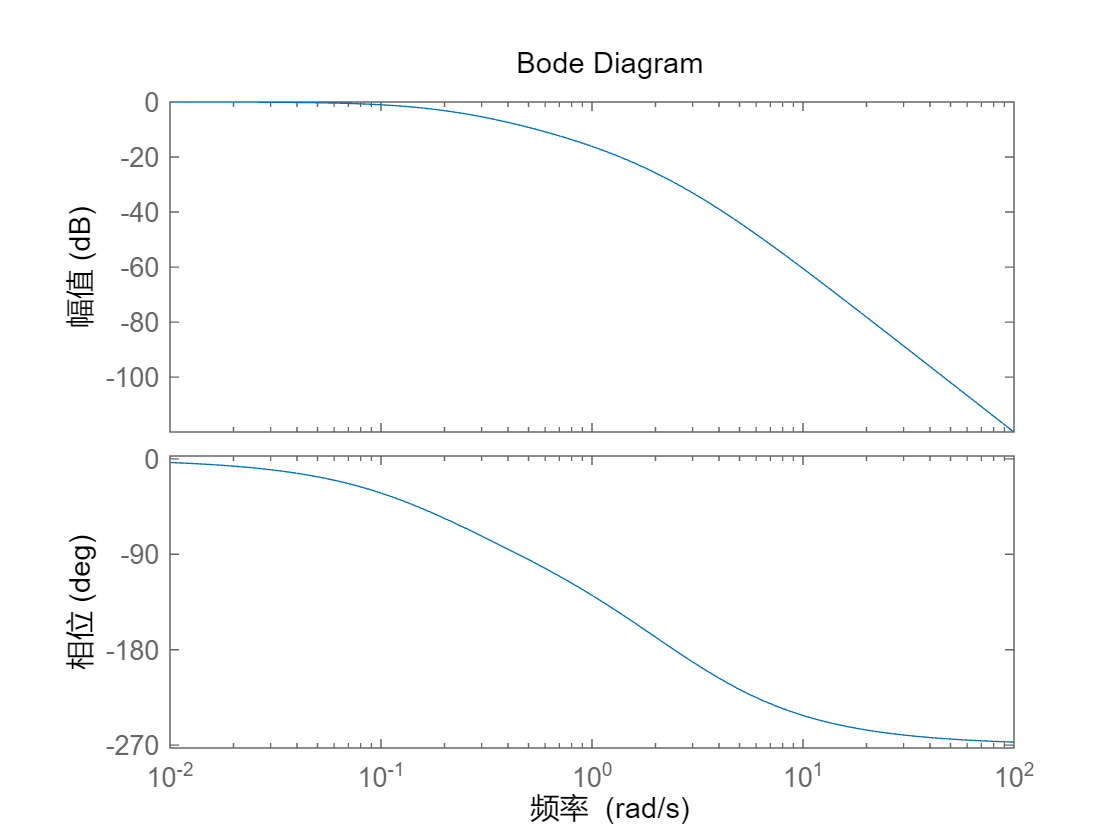

bode(gs)